# Nodal Analysis

[⇦ DC Circuit Analysis Overview](matlab: OpenOverview)

**Learning Goals**

- Use nodal analysis to compute voltages.

- Solve the matrix form of circuit equations in MATLAB.

- Model and analyze linear circuits in Simscape.

## Overview

If a linear circuit has only one loop, it is typically a simple task to solve for the voltages. However, if the circuit has several branches, the voltages at each point are not obvious. It is possible to use mesh analysis to identify mesh currents and then compute the node voltages. Nodal analysis allows you to solve for the node voltages directly without computing the currents first. In the essential step of this technique, Kirchhoff's current law is applied to identify an equation for each node.

### **Kirchhoff's current law (KCL)**

The sum of currents entering a node equals the sum of currents flowing out of it. 

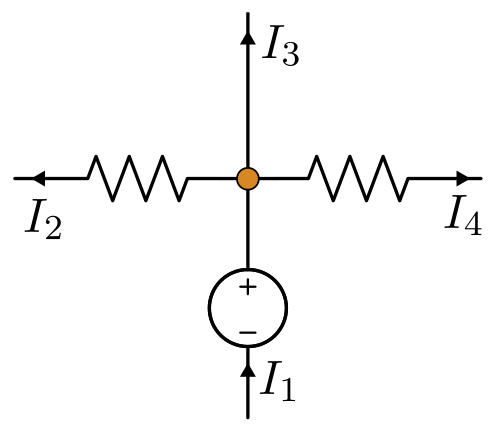

*At this node, Kirchhoff's current law implies *$I_1 = I_2 + I_3 + I_4 $

When applying KCL in nodal analysis, the currents are typically written in terms of node voltages. Node voltages are defined as the potential difference between a node and a defined ground node.

### **Steps**

There are three major steps in nodal analysis:

- Define the node voltage variables and a reference node.

- Write an equation for each node by applying KCL.

- Set up a matrix equation for the node voltages and solve.

In the first step, node voltages are defined. A node voltage can be defined anywhere two circuit elements meet. However, you should only define node voltage variables where the voltage cannot be directly calculated from a neighbor. Typically, this means you only need to define node voltages where three or more circuit elements are connected.

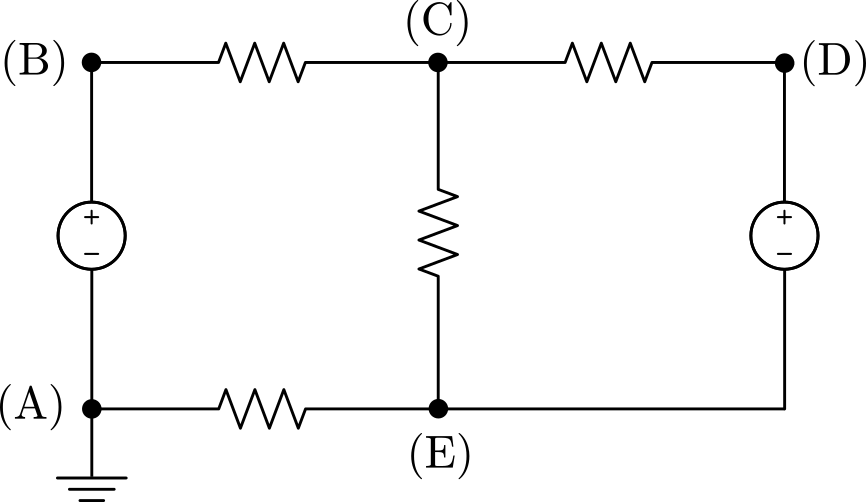

*Example circuit*

Consider the example circuit shown. While you can define node voltage variables at any labeled point, it is not necessary. First, the ground has been defined at node (A), so the node voltage is zero at point (A). The voltage at point (B) can be directly calculated by adding the voltage source between (A) and (B). Similarly, the value at (D) could be calculated based on the voltage source between (E) and (D). This implies a good option is to define node voltages at (C) and (E): $V_C$ and $V_E$.

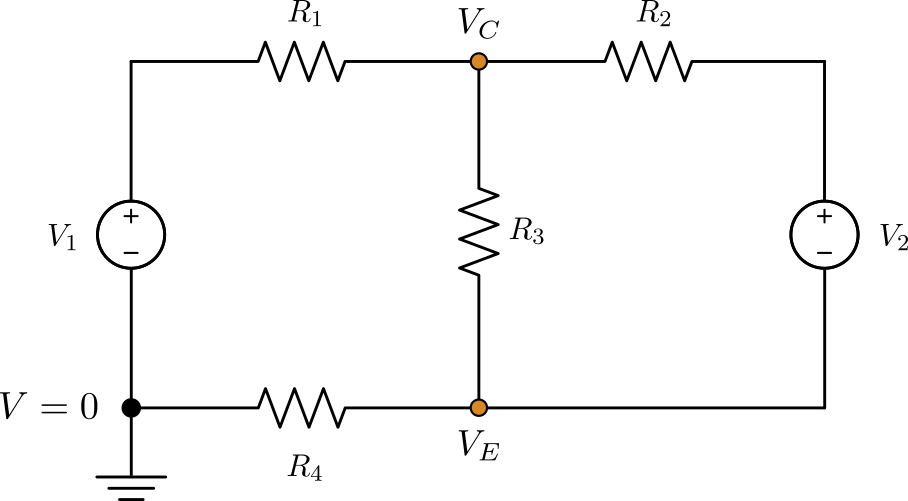

*Node voltages in the example circuit*

With the node voltages selected, you can write an equation for each node. At node (E), you can define three currents. For simplicity, define all three currents as flowing out of (E) (the defined direction is arbitrary).

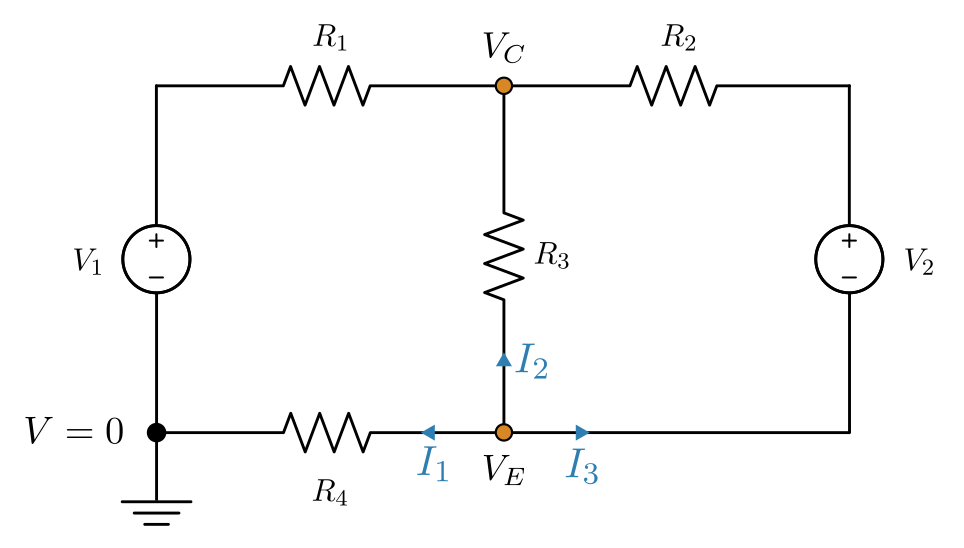

*Current definitions*

With these definitions, Kirchhoff's current law implies


$$I_1 + I_2 + I_3 = 0$$


Recall that Ohm's law relates current through a resistor to voltage across it as $I = V/R$. Applying Ohm's law and incorporating the voltage source implies


$$\frac{V_E - 0}{R_4} + \frac{V_E - V_C}{R_3} + \frac{V_E + V_2 - V_C}{R_2} = 0$$


**Note:** Defining the current labels $I_1$, $I_2$, etc. is not necessary. Typically, the directions are selected, and Ohm's law is applied as the equation is written.

The derived equation has two unknowns: $V_C$ and $V_E$. To be solved, an additional equation is needed. Applying KCL again to node (C) will yield an additional equation. To solve the resulting system, you can define a matrix system. Matrices provide a natural framework: they can concisely capture the many linear equations that model a circuit network. In the following example, the matrix form is derived and used to solve for the node voltages.

## **Example **

Use nodal analysis to solve for the voltages through the circuit with the given values.

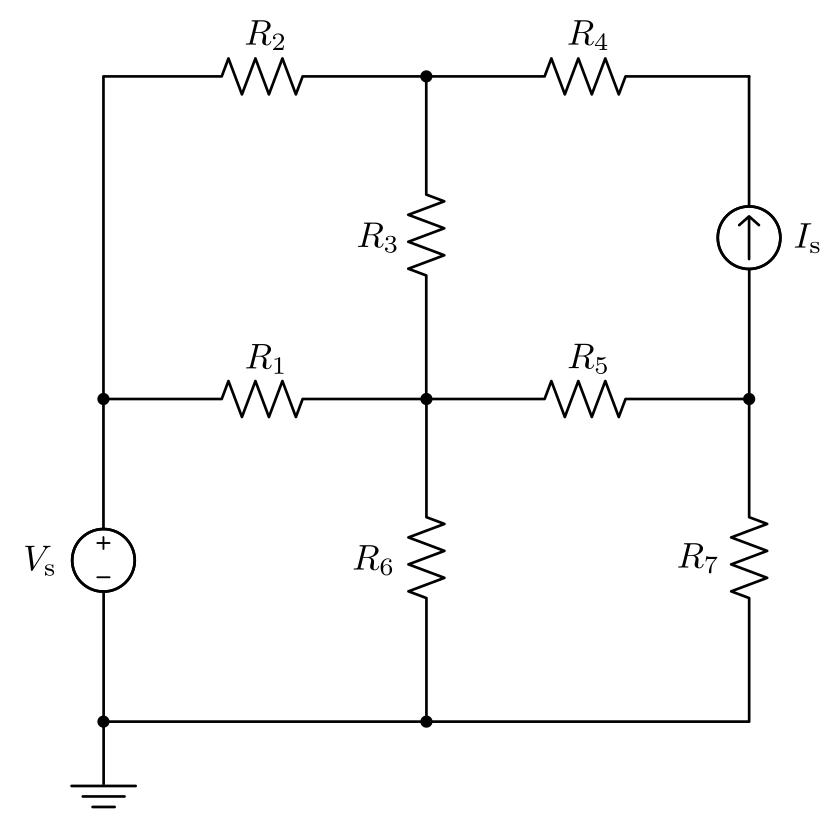

*Circuit diagram*

    
$$\begin{array}{l}
R_1 = 200 \ \Omega
\\
R_2 = 140 \ \Omega
\\
R_3 = 330 \ \Omega
\\
R_4 = 2 \ \text{ k} \Omega
\\
R_5 =  330 \ \Omega
\\ 
R_6 = 50 \ \Omega
\\ 
R_7 = 50 \ \Omega
\end{array}$$
         
$$\begin{array}{l}
V_\text{s} = 3 \ \text{V}
\\
I_\text{s} = 200 \ \text{mA}
\end{array}$$


### **Step 1.** **Define reference and node voltages**

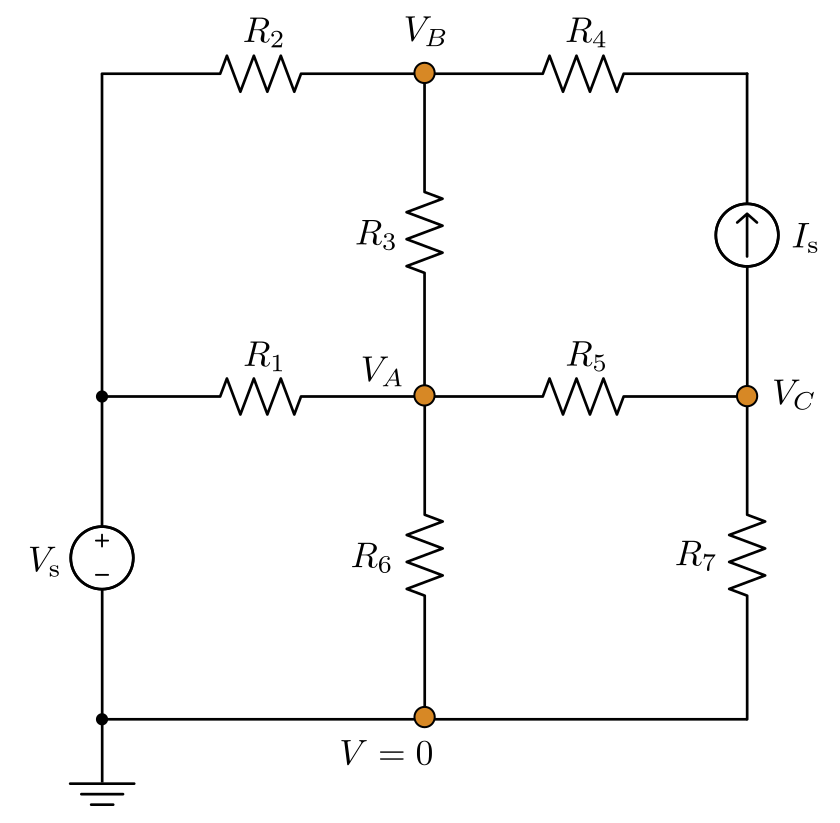

*Node voltages labeled in the circuit*

Each unknown node is assigned a voltage. Note that the left-side branch has a known voltage, $V_s$, so a variable is not required.

### **Step 2. A**pply KCL

For simplicity, all currents are defined as flowing into each node. At first, this might appear to generate inconsistent definitions for the branch currents. However, this is acceptable since the current definitions are not used directly. They are simply placeholders for writing the node voltage equations.

**Node A.** Four currents enter node A, resulting in four terms:


$$\frac{V_\text{s} - V_A}{R_1} + \frac{V_B-V_A}{R_3} + \frac{V_C - V_A}{R_5} + \frac{0 - V_A}{R_6} = 0$$


**Node B. **Three currents enter node B. One of these currents is constant due to the current source $I_\text{s}$.


$$\frac{V_\text{s} - V_B}{R_2} + \frac{V_A - V_B}{R_3}  + I_\text{s} = 0$$


**Node C. **The third node also has three branches.


$$\frac{V_A - V_C}{R_5} + \frac{0 - V_C}{R_7} - I_\text{s} = 0$$


### **Step 3. **Set up the matrix equation and solve

**Set up the matrix equation.**

Before setting up the matrix equation, rewrite the equations in terms of the unknown $V_i$'s and move the constant terms to the right-hand side.

**Node (A):** $- \left( \frac{1}{R_1}  + \frac{1}{R_3} + \frac{1}{R_5} + \frac{1}{R_6} \right) \cdot V_A + \frac{1}{R_3} V_B + \frac{1}{R_5} V_C = - \frac{V_\text{s}}{R_1}$

**Node (B): **$\frac{1}{R_3} V_A - \left( \frac{1}{R_2} + \frac{1}{R_3} \right) \cdot V_B  = - I_\text{s} - \frac{V_\text{s}}{R_2}$

**Node (C): **$\frac{1}{R_5} V_A - \left( \frac{1}{R_5} + \frac{1}{R_7} \right) \cdot V_C = I_\text{s}$

The matrix equation is created by defining the variable of unknown node voltages

    
$$\mathbf{V} = \left[ \begin{array}{l} V_A \\ V_B \\ V_C \end{array} \right]$$
 

Then, the system is converted into matrix notation $\mathbf{M} \mathbf{V} = \mathbf{b}$, using the coefficients of the unknown $V_i$'s to build the coefficient matrix.


$$\left( \begin{array}{ccc}  
{R_1}^{-1} + {R_3}^{-1}  + {R_5}^{-1} + {R_6}^{-1}   & -{R_3}^{-1}  &  \ \ - {R_5}^{-1} \\
-{R_3}^{-1}  &  {R_2}^{-1} + {R_3}^{-1}  &  0 \\
-{R_5}^{-1}  & 0 & {R_5}^{-1} + {R_7}^{-1}  \\
\end{array} \right)
\left( \begin{array}{l} V_A \\ V_B \\ V_C \end{array} \right)
=
\left( \begin{array}{c} V_\text{s}{R_1}^{-1} \\ I_\text{s} + V_\text{s}{R_2}^{-1}\\ - I_\text{s} \end{array} \right)$$


**Solve the matrix equation in MATLAB.**

To solve the matrix system in MATLAB, start by defining the values of the resistors and voltage sources. Be sure that the units are consistent.

% Define the values
R1 = 200;
R2 = 140;
R3 = 330;
R4 = 2000;
R5 = 330;
R6 = 50;
R7 = 50;
Vs = 3;
Is = 0.2;

Next, define the coefficient matrix $\mathbf{M}$ and constant vector $\mathbf{b}$.

% Set up the matrix equation
M = [-(1/R1+1/R3+1/R5+1/R6),       1/R3,          1/R5; 
           1/R3,                -(1/R2+1/R3),        0;
           1/R5,                       0,      -(1/R5+1/R7)];
b = [-Vs/R1; -Is-Vs/R2; Is];

Then, solve the matrix system with the backslash (`\`) operator. To solve $\mathbf{M} \mathbf{V} = \mathbf{b}$, use

% Solve for the node voltages
V = M\b

## **Simscape model analysis**

A long calculation like the one shown above is prone to errors. You can create a model of the electrical circuit in Simscape and then measure the node voltages to check your work. For this example, a model of the circuit has already been created.

A virtual multimeter is included for taking measurements in the circuit. To use the model to validate the result, complete the following steps.

1. Open the example model:

[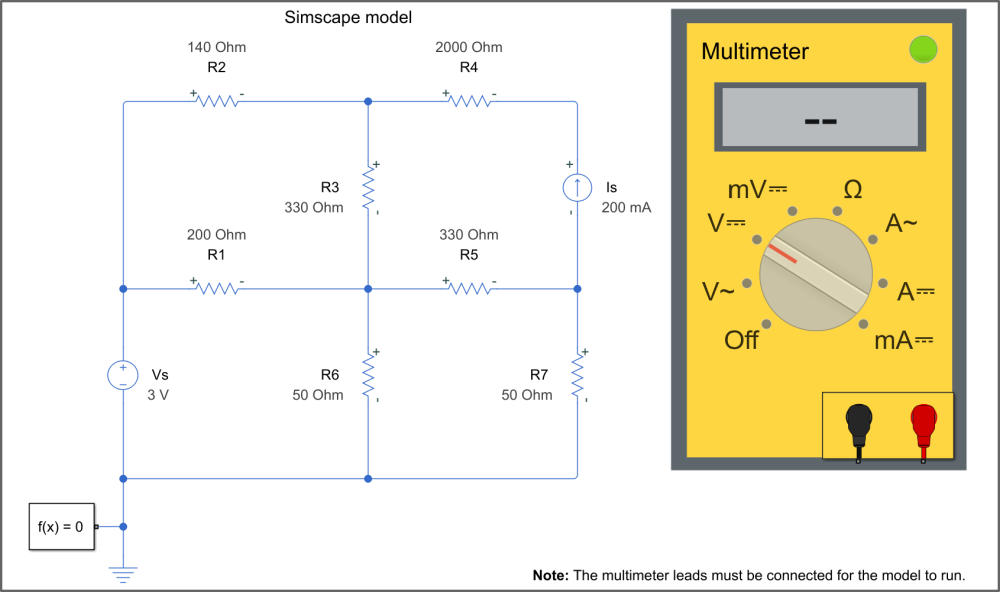](matlab: NodalAnalysisExample)

[`NodalAnalysisExample.slx`](matlab: NodalAnalysisExample)

**Note: **Watch [this 2-minute instructional video](https://user-images.githubusercontent.com/81383420/145589989-f7ae4a32-cab3-405d-b7e8-476e34d697b5.mp4) to learn how to use the virtual multimeter.

2. Measure the node voltage at node B. 

- Connect the black lead (negative) to ground and the positive lead (red) to the node you want to measure.

- Run the model. 

- Set the voltmeter to measure DC current (V⎓).

- Stop the model when the measurement is complete.

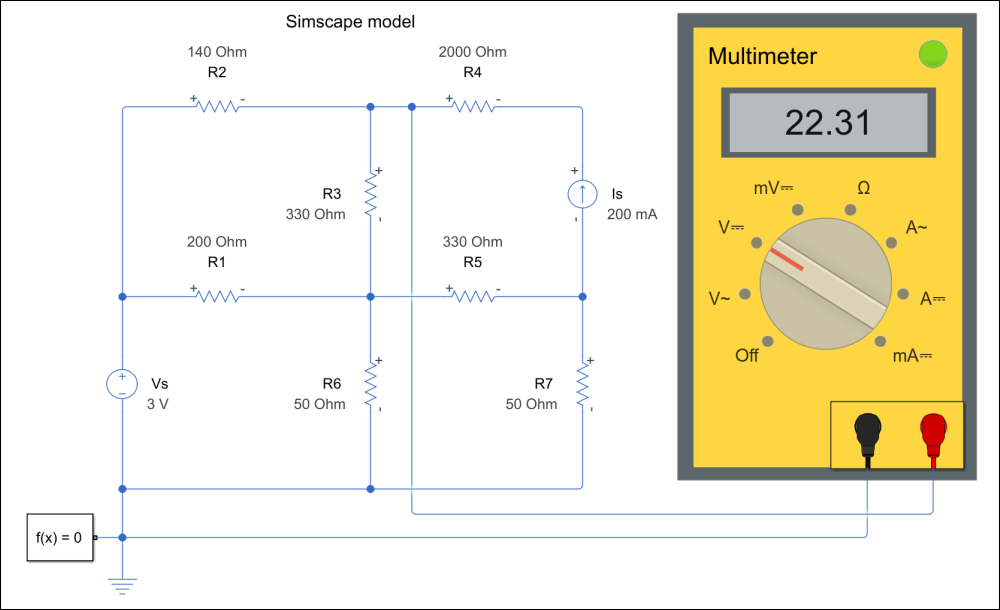

*Simscape model measuring the node voltage *$V_B$

3. Repeat step 2 to measure the node voltage at A and C. Do the measurements match the result of the nodal analysis?

[⇦ DC Circuit Analysis Overview](matlab: OpenOverview)